## BECS4 Optimization Methods Final Project

## Introduction

The detection and classification of handwritten digits is a very common task for the introduction to neural networks. For this project we use a prewritten neural network workflow from [Johannes Langelaar](https://ch.mathworks.com/matlabcentral/profile/authors/8723697)

The mnist data on handwritten digits is already preprocessed and ready to use.

Mathworks: https://ch.mathworks.com/matlabcentral/fileexchange/90461-neural-network-training-with-adam-optimizer-from-scratch/?s_tid=LandingPageTabfx

Originaly there are **60'000** digits to train the model and **10'000** for testing. To increase the difficulty and have a better comparability between methods, only **20'000** digits were used for training and **5000** for testing. 

**Explanation for the usage of genetic algorithms in neural networks**

https://towardsdatascience.com/gas-and-nns-6a41f1e8146d

### NN-Architecture

The NN-architecture was changes compared to the original implementation. Instead of 100 and 50 for the first and second hidden layer, we decided for 128 and 64 which is the more common approach for neural networks. 

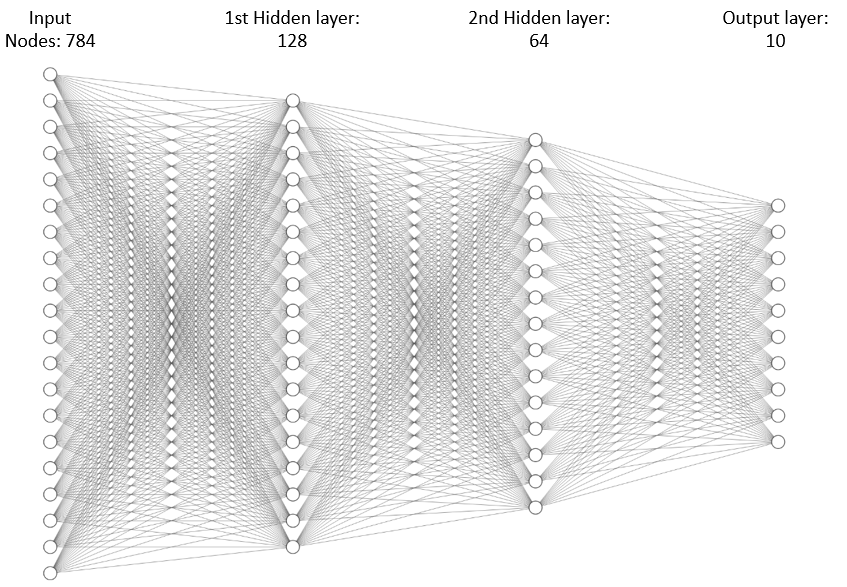

### Input digits (28X28)

The digits are 28x28 grey scale pictures ranging from 0 to 9. 

## Project goal:

The first goal of the project is to evaluate different optimization methods to improve the backpropagation of the model. The authors of the original project implemented the following optimizers and used a mini-batch gradient descent.

- Adam

- Stochastic gradient descent

To get a a wider option space the following optimizers were additionaly implemented:

- Adagrad

- Adadelta     

These additional optimizers are coded in the optimizer.m file.

The second goal was to implement a genetic algorithm which finds the best initial weights and biases for all layer to increase the performance. The practicality of this approach may be used if time and computational ressources are limited or the model gets stuck in a local optimum despite the continuation of training.

As a workflow template we use the publication of Ecer et al. https://www.mdpi.com/1099-4300/22/11/1239

The following steps were implemented:

- Train 10 individual models over 3 epochs with random weights. 

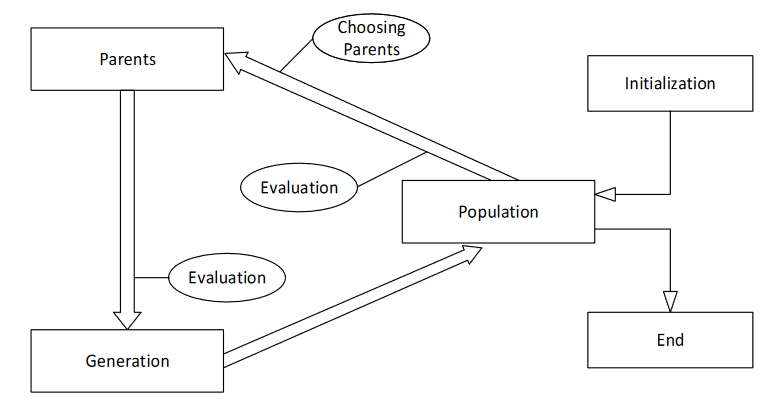

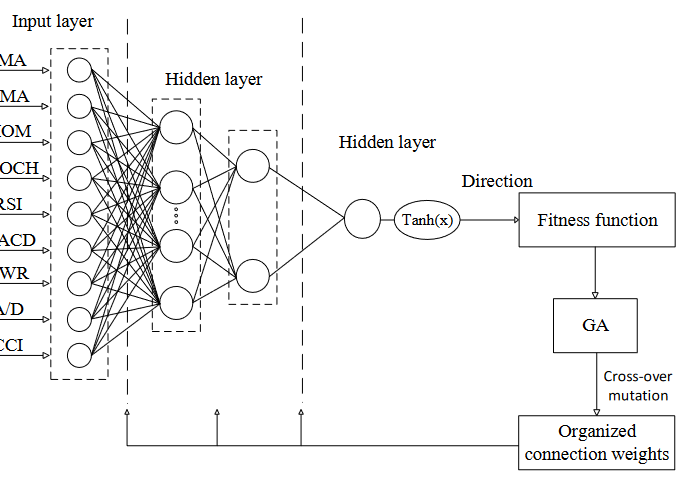

#### Data preprocessing

%cd 'C:\Users\kevin yar\OneDrive - ZHAW\KEVIN STUFF\ZHAW\_PYTHON_R\_GITHUB\becs4\neural_network_mninst'
%cd neural_network_mninst\

%% training data
disp('Loading data...')

Loading data...



% load train data
train_data = load('mnist_train.csv');

%reduce data volume to increase difficulty
train_data = train_data(1:10000,:);

%start progress bar
f = waitbar(0, 'Starting');

labels = train_data(:,1);
y = zeros(10,length(train_data)); % output labels for training
for i = 1:length(train_data)
    waitbar(i/length(train_data), f, sprintf('Training Data: %d %%', floor(i/length(train_data)*100)));
    %one hot encoding
    y(labels(i)+1,i) = 1;
end
close(f)
% preprocessing
images = train_data(:,2:785);
images = images/255;
images = images'; % Input vectors for training

%% test data
    
% load test data
test_data = load('mnist_test.csv');
%reduce test data
test_data = test_data(1:5000, :);

%progress bar
f = waitbar(0, 'Starting');

test_labels = test_data(:,1);
test_y = zeros(10 ,length(test_data));
for i = 1:length(test_data)
    waitbar(i/length(test_data), f, sprintf('Test Data: %d %%', floor(i/length(test_data)*100)));
    test_y(test_labels(i)+1,i) = 1;
end
close(f)
% preproessing
test_images = test_data(:,2:785);
% normalize data
test_images = test_images/255;
% transposing
test_images = test_images';


## **Optimizer comparison**

To evaluate the performance of the added optimizers the models are trained over 5 epochs. 

**Specify hyperparameters for **


%set NN size
size_hl1 = 128; % Number of neurons in the first hidden layer
size_hl2 = 64; % Number of neurons in the second hidden layer

%set learning rate
lr = 0.001;

epochs = 10; % Number of training epochs
batch_size = 100; % Mini-batch size

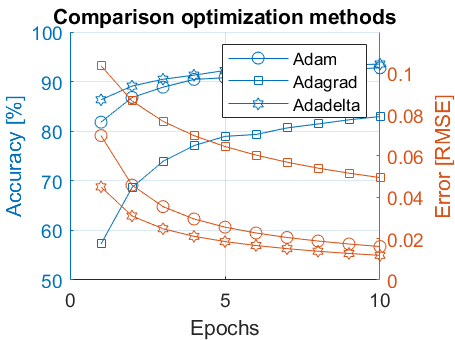

visModels =   1×3 NN array with properties:

    mlp
    grad
    m
    optim
    error4
    rmse
    crossEnt


visModels = VisualizeOptMethods(epochs, ...
                                batch_size, ...
                                size_hl1, ...
                                size_hl2, ...
                                lr, ...
                                train_data, ...
                                images, ...
                                y, ...
                                test_data, ...
                                test_images, ...
                                test_labels)

All the trained models are stored in visModels. The optimizer can be called with

ex. visModels(1).optim.opt

**Interpretation:**

The newly added optimizers Adadelta and Adagrad are showing different performance. Adagrad has a slower performance increase compared to Adadelta and Adam. Furthermore, Adadelta seems to have a comparable accuracy developement with Adam but manages to have a generaly lower Error (RMSE). 

### Visualizing weights and biases distribution

To get a better understanding how to connect the genetic algorithm with the neural network the range of weights and biases is needed for the mutation process. For this reason a distribution plot of the two hyperparameter is needed. 

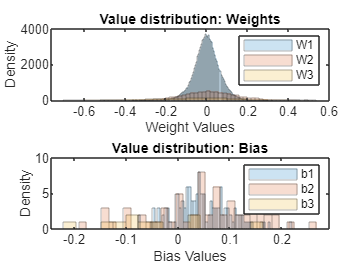

%model 1=adam, 2=adagrad, 3=adadelta
model = 3;

figure('Name','Comparison Value distribution')
    subplot(2,1,1)
    histogram(visModels(model).mlp.W1, 'edgealpha', 0.2, 'facealpha',0.2, "DisplayName", "W1")
    hold on
    histogram(visModels(model).mlp.W2, 'edgealpha', 0.2, 'facealpha',0.2, "DisplayName", "W2")
    hold on
    histogram(visModels(model).mlp.W3, 'edgealpha', 0.2, 'facealpha',0.2, "DisplayName", "W3")
    hold on
    title('Value distribution: Weights');
    xlabel('Weight Values');
    ylabel('Density');
    legend show
    
    subplot(2,1,2)
    histogram(visModels(model).mlp.b1,64, 'edgealpha', 0.2, 'facealpha',0.2, "DisplayName", "b1")
    hold on
    histogram(visModels(model).mlp.b2, 32,'edgealpha', 0.2, 'facealpha',0.2, "DisplayName", "b2")
    hold on
    histogram(visModels(model).mlp.b3, 16, 'edgealpha', 0.2, 'facealpha',0.2, "DisplayName", "b3")
    title('Value distribution: Bias');
    xlabel('Bias Values');
    ylabel('Density');
    
    hold off
    legend show

**Interpretation:**

As expected the value distributions for the weights and biases are flattening the deeper the model goes. This change of distribution is mainly due to the more defining neurons responsible for the right classification. Therefore these neurons must have generally higher values than the not important neurons. 

## **Genetic Algorithm**

**Specify hyperparameters for Genetic Algorithm**


%set NN size
size_hl1 = 128; % Number of neurons in the first hidden layer
size_hl2 = 64; % Number of neurons in the second hidden layer

%set learning rate
lr = 0.001;

%set optimizer
optimizer = "Adam";

epochs = 1; % Number of training epochs
batch_size = 100; % Mini-batch size

nrOfModels = 10;

**Train 10 models**

modelArray = trainMod( ...
    size_hl1, ...
    size_hl2, ...
    optimizer, ...
    lr, ...
    epochs, ...
    batch_size, ...
    images, ...
    train_data, ...
    y, ...
    nrOfModels)

**Run the genetic algorithm on these models**

evolvedModels = genAlg(modelArray, test_data, test_images, test_labels, 0.09, 0.01);
%print the final accuracy of each model
%finalModel = evolvedModels.nnMatrix(evolvedModels.index(1))

